# Author: Lu, Chia-Feng 2013.11.28

clear, close all
clc

## initialize parameters

samplerate=500; % in Hz
N=1000; % data length

freq1=5; % in Hz
freq2=7; % in Hz
taxis=[1:N]/samplerate;

PCnum=2;  % the number of PC used to reconstruct signals

## generate test signals

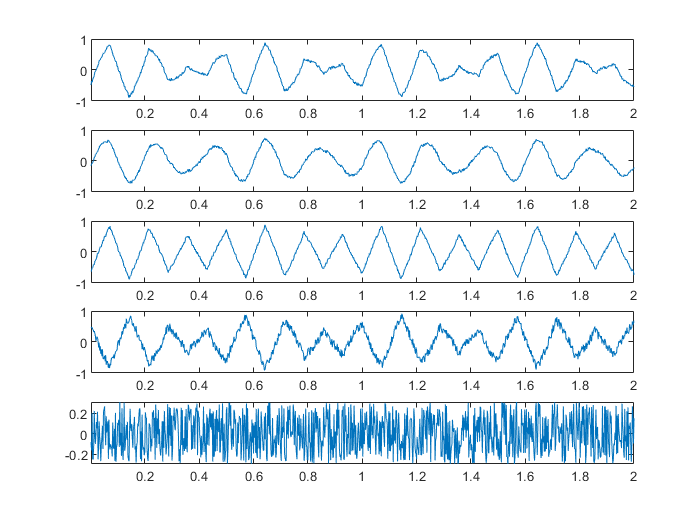

C1 = 0.75*sin(2*pi*freq1*taxis);        % 1st component: a sine wave
C2 = sawtooth(2*pi*freq2*taxis,0.5);    % 2nd component: a triangular wave

% Combine data in different proportions
X(1,:) = 0.5*C1 + 0.5*C2 + 0.1*rand(1,N);
X(2,:) = 0.7*C1 + 0.2*C2 + 0.1*rand(1,N);
X(3,:) = 0.2*C1 + 0.7*C2 + 0.1*rand(1,N);
X(4,:) = -0.3*C1 - 0.6*C2 + 0.3*rand(1,N);
X(5,:) = 0.6*rand(1,N);    % Noise only

% Center data by subtracting mean
X = X - mean(X,2)*ones(1,N);

figure, 
for i=1:size(X,1)
    subplot(size(X,1),1,i)
    plot(taxis,X(i,:)),xlim([taxis(1) taxis(end)])
end

## Principal Components Analysis using princomp funcion (using eig and svd)

[U,PC,eigenVal]=pca(X')

U =     0.5295    0.1534   -0.0161    0.2810    0.7854
    0.4211    0.7932   -0.0226    0.0000   -0.4393
    0.5273   -0.5212    0.0079    0.5100   -0.4360
   -0.5140    0.2734   -0.0201    0.8128    0.0019
    0.0036    0.0300    0.9994    0.0169    0.0062


PC =    -0.8935    0.2610   -0.0851   -0.0878   -0.0390
   -0.7922    0.3038   -0.1669   -0.0147    0.0238
   -0.7478    0.2795    0.1955    0.0141   -0.0562
   -0.6764    0.2665   -0.2522   -0.0331   -0.0061
   -0.5734    0.2843   -0.2504    0.0282   -0.0189
   -0.4944    0.2716   -0.1129   -0.0175   -0.0215
   -0.4412    0.3901    0.2101    0.0338   -0.0171
   -0.2969    0.3317   -0.0180    0.0520    0.0226
   -0.1905    0.3450   -0.1079    0.0044   -0.0065
   -0.0619    0.3086   -0.0239   -0.1079   -0.0021


eigenVal =     0.5428
    0.0861
    0.0304
    0.0051
    0.0008


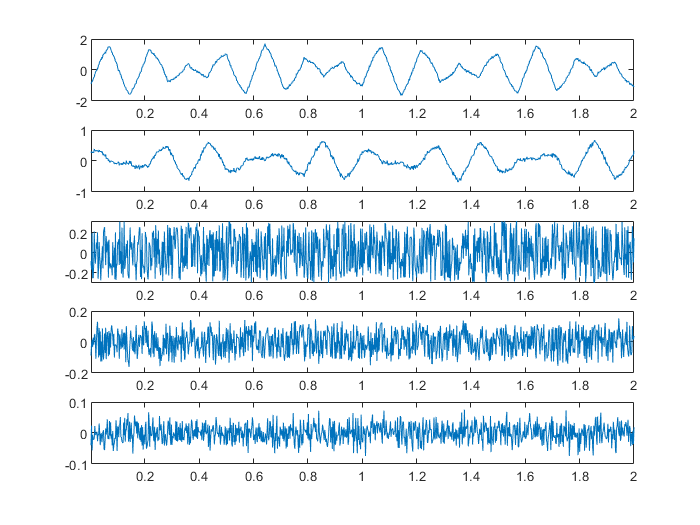


for i=1:size(X,1)
    eigen_perc(i)=sum(eigenVal(1:i))/sum(eigenVal)*100;  % calculate accumulated percentage of eigenvalues
end

figure, 
for i=1:size(PC,2)
    subplot(size(PC,2),1,i)
    plot(taxis,PC(:,i)),xlim([taxis(1) taxis(end)])
end

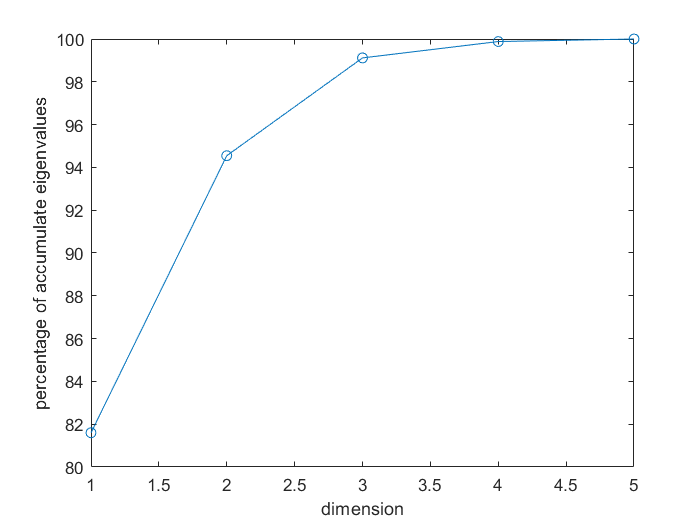


figure,plot(eigen_perc,'-o')
xlabel('dimension'),ylabel('percentage of accumulate eigenvalues')

## Check the covariance of principal components (PC)

cov(PC)  % make sure if the PCs are uncorrelated !

ans =     0.5428    0.0000   -0.0000    0.0000    0.0000
    0.0000    0.0861   -0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.0304    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0051   -0.0000
    0.0000    0.0000    0.0000   -0.0000    0.0008


% the off-diagonal terms should be 0

## Reconstruct the Signal only use the first PCnum PCs

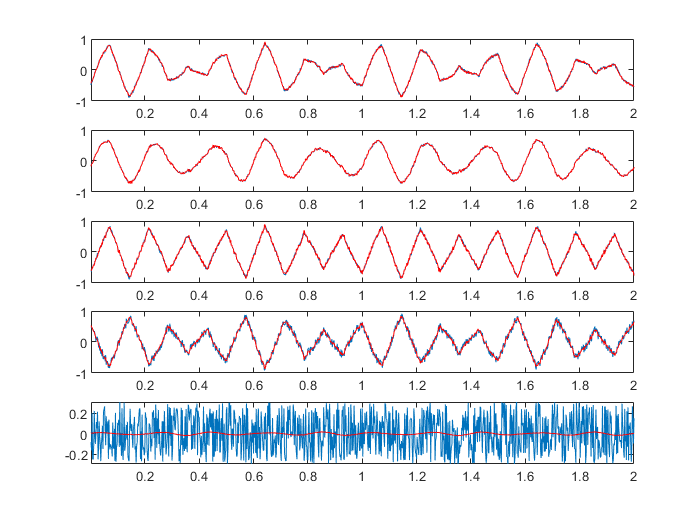

newX = U(:,1:PCnum)*PC(:,1:PCnum)';

figure, 
for i=1:size(newX,1)
    subplot(size(newX,1),1,i)
    plot(taxis,X(i,:)),hold on
    plot(taxis,newX(i,:),'r'),xlim([taxis(1) taxis(end)])
end